Problem 1

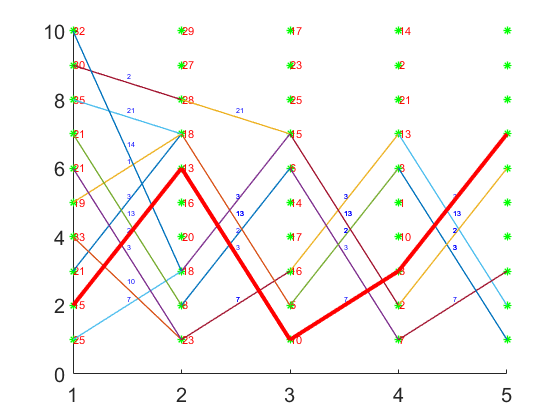

load('Problem1_Data.mat',"A");

C = zeros(10,10);
p = zeros(10,10);

for k = 9:-1:1
    for i = 1:10
        [m,n] = min(A(i,:)+transpose(C(:,(k+1))));
        C(i,k) = m;
        p(i,k) = n;
    end
end

alpha = [];

alpha(1) = min(find(C(:,1) == min(C(:,1))));
for k = 2:9
    alpha(k) = p(alpha(k-1),k-1);
end

X = zeros(10,10);
Y = zeros(10,1);
for i = 1:10
        X(:,i) = i;
        Y(i) = i;
end

figure (1);
clf;
set(gca,'fontsize',15);
xlim([1 5]);
ylim([0 10]);
hold on;
for i = 1:5
    plot(X(:,i),Y,'g*','Linewidth',1);
    hold on;
end

for i=1:4
    for j = 1:10
        str = sprintf('%d',C(j,i+5));
        text(X(j,i),Y(j),str,'fontsize',8,'color','red');
    end
end

temp = zeros(10,5);
Index = zeros(10,5);
for i = 1:10
       [temp(i,1),Index(i,1)] = min(A(i,:));
end
for j = 2:5
    for i = 1:10
        [temp(i,j),Index(i,j)] = min(A(Index(i,j-1),:));
    end
end
Index = [(1:10)' Index(:,1:4) ];

for i=1:4
    for j=1:10
        plot([i i+1],[Y(Index(j,i)) Y(Index(j,i+1))],'Linewidth',1);
        str=sprintf('%d',temp(j,i));
    text((2*i+1)/2,(Y(Index(j,i))+Y(Index(j,i+1)))/2+0.2,str,'fontsize',5,'color','blue');
    end
end

for i = 1:4
    plot([i i+1], [Y(Index(2,i)) Y(Index(2,i+1))],'Linewidth',3,'Color','red')
end

Problem No 2

clear;
load('Problem2_Data.mat');

[n,d]=size(X);
N=n;
C=zeros(n,N);
i0=6;
j0=9;
I=zeros(n,N);
I(j0,N)=1;
M=1000;
p=zeros(n,N);
for k=N-1:-1:1
    flag=0;
    for i=1:n-1
        vec=D(i,:)+C(:,k+1)'+M.*(1-I(:,k+1)');
        [C(i,k) p(i,k)]=min(vec);
        if C(i,k)<M
            I(i,k)=1;
        else
            I(i,k)=0;
        end
    end
    if I(i0,k)==1
        disp(k);
        break
    end
end

    42



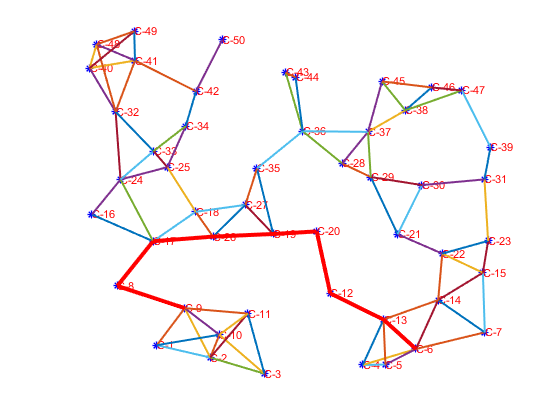

alpha=zeros(N);
alpha(k)=i0;
for kk=k:N-1
    alpha(kk+1)=p(alpha(kk),kk);
end

figure (2);

set(gca,'fontsize',5);
hold on;
plot(X(:,1),X(:,2),'b*','Linewidth',1);
for i=1:n
    str=sprintf('C-%d',i);
    text(X(i,1),X(i,2),str,'fontsize',8,'color','red');
end
for i=1:n
    for j=1:n
        if D(i,j)<Inf
            plot([X(i,1) X(j,1)],[X(i,2) X(j,2)],'Linewidth',1.5);
        end
    end
end
axis equal off;
idp=find(alpha>0);
for i=1:length(idp)-1
    plot([X(alpha(idp(i)),1) X(alpha(idp(i+1)),1)],[X(alpha(idp(i)),2) X(alpha(idp(i+1)),2)],'Linewidth',3,'color','red');
    hold on;
end